## Set parameters

clear all; 
clc;
tile_ratio = 40; % number of tiles for width of image
tile_dir = strcat(pwd, filesep, 'Tiles');
target_Img = imread('mosaic_target2.jpg');
output_file_name = 'CompositeImage.jpg';
dir_path = '/Users/xucaiyue/Documents/MATLAB/image/';
file_types = 'JPG';
Using_Adjustment = true;
Using_HoG = true;
num_closest = 20;

## Get original img size

img_size = size(target_Img);
img_size = img_size(1:2);

## Calculate tile values

tile_pixels = floor(img_size(1)/tile_ratio);
tile_size = [tile_pixels tile_pixels];
new_height = floor(img_size(2)/tile_pixels);
num_tiles = [tile_ratio new_height];
new_size = [tile_ratio new_height].*tile_pixels;
target_Img = imresize(target_Img, new_size);

## Get all directory images and store the name to array

dir_files = dir(dir_path);
mosaic_ind = 1;
for dir_ind = 1:length(dir_files)    
    file_name = dir_files(dir_ind).name;
    [~, ~, ext] = fileparts(file_name);
    if max(strcmpi(ext(2:end), file_types))
        mosaic_files{mosaic_ind} = file_name;
        mosaic_ind = mosaic_ind+1;
    end
end

## Resize archive images into tiles directory

progress = waitbar(0, 'Resizing the tiles');

num_files = length(mosaic_files);
mosaic_imgs = cell(1, num_files);
if ~exist(tile_dir, 'dir')
   mkdir(tile_dir);
end
for mosaic_ind = 1:num_files
    img = imread([dir_path, filesep, mosaic_files{mosaic_ind}]);
    new_img = uint8(imresize(img, tile_size));
    tiles{mosaic_ind} = new_img;
    imwrite(new_img, [tile_dir, filesep, strcat(num2str(mosaic_ind),'.jpg')], 'jpg');
    waitbar(mosaic_ind/num_files, progress);
end
close(progress);

## Calculate the averages of RGB in tile directory

for mosaic_ind = 1:num_files
    % calc average vals for tiles
    cur_tile = tiles{mosaic_ind};
    RGB_vals{mosaic_ind} = mean(reshape(cur_tile, [], 3), 1);
    hog1{mosaic_ind} = extractHOGFeatures(cur_tile);
end

## Find closest matching tile for each tile of image

pic_map = zeros(num_tiles);
for row_tile = 1:num_tiles(1)
    for col_tile = 1:num_tiles(2)
        % get mean vals for the image tiles
        cur_tile = target_Img(tile_pixels*(row_tile-1)+1:tile_pixels*(row_tile), ...
        tile_pixels*(col_tile-1)+1:tile_pixels*(col_tile),:);
        cur_RGB = mean(reshape(cur_tile, [], 3), 1);

        hog2 = extractHOGFeatures(cur_tile);
        
        % store 20 best and randomly choose one
        min_list = zeros(1,num_closest);
        min_indices = 1:num_closest;
        for i = 1:num_closest 
            min_list(i) = sqrt(sum((RGB_vals{i}-cur_RGB).^2));
        end
        for i = (num_closest+1):num_files 
            temp = sqrt(sum((RGB_vals{i}-cur_RGB).^2));
            max_i = find(min_list == max(min_list(:)));
            if temp < min_list(max_i)
                min_list(max_i) = temp;
                min_indices(max_i) = i;
            end
        end

        if Using_HoG == true
            shortest_dist = pdist2(hog1{min_indices(1)},hog2,'euclidean');
            shortest_index = min_indices(1);
            for i = 1:num_closest
                cur_dist = pdist2(hog1{min_indices(i)},hog2,'euclidean');
                if cur_dist < shortest_dist
                    shortest_dist = cur_dist;
                    shortest_index = min_indices(i);
                end
            end
            pic_map(row_tile, col_tile) = shortest_index;
        else
            image_index = min_indices(randi(num_closest));
            pic_map(row_tile, col_tile) = image_index;
        end
    end
end

## Take mapping of tilenails and create photomosaic

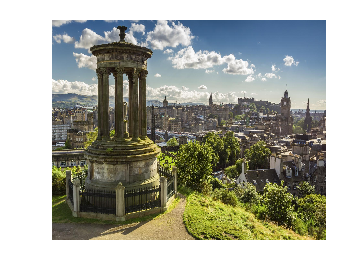

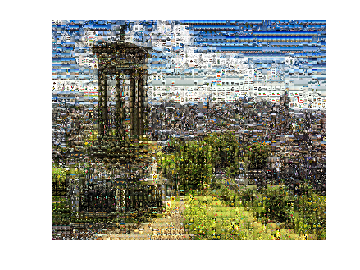

if Using_Adjustment == true
    for row_tile = 1:num_tiles(1)
        cur_tile2 = target_Img(tile_pixels*(row_tile-1)+1:tile_pixels*(row_tile), ...
        tile_pixels*(1-1)+1:tile_pixels*(1),:);
        mean_cur_tile = mean(mean(cur_tile2, 1), 2);
        cur_row = tiles{pic_map(row_tile, 1)};
        mean_cur_row = mean(mean(cur_row, 1), 2);
        adjustment_factor = mean_cur_tile ./ mean_cur_row;
        cur_row = uint8(double(cur_row) .* adjustment_factor);

        for col_tile = 2:num_tiles(2)
            cur_tile3 = target_Img(tile_pixels*(row_tile-1)+1:tile_pixels*(row_tile), ...
            tile_pixels*(col_tile-1)+1:tile_pixels*(col_tile),:);
            mean_cur_tile2 = mean(mean(cur_tile3, 1), 2);
            cur_row3 = tiles{pic_map(row_tile, col_tile)};
            mean_cur_row2 = mean(mean(cur_row3, 1), 2);
            adjustment_factor2 = mean_cur_tile2 ./ mean_cur_row2;
            cur_row3 = uint8(double(cur_row3) .* adjustment_factor2);
            cur_row = horzcat(cur_row, cur_row3);
        % Horizontally concatenate tiles
        end
        if row_tile == 1
            mosaic = cur_row;
        else
            mosaic = vertcat(mosaic, cur_row);
        % Vertically concatenate tiles 
            clear cur_row;
        end
    end
else
    for row_tile = 1:num_tiles(1)
        cur_row = tiles{pic_map(row_tile, 1)};
        for col_tile = 2:num_tiles(2)
            cur_row = horzcat(cur_row, tiles{pic_map(row_tile, col_tile)});
        % Horizontally concatenate tiles
        end
        if row_tile == 1
            mosaic = cur_row;
        else
            mosaic = vertcat(mosaic, cur_row);
        % Vertically concatenate tiles 
            clear cur_row;
        end
    end
end
imwrite(mosaic, output_file_name, 'jpg');

figure; 
imagesc(mosaic); 
axis off;
figure;
imagesc(target_Img); 
axis off;